clc; clear;
a = 9; % 学号

% Step1=指定GA的参数
num = 20; % 个体数量
num_runs = 5; % 设置算法运行次数
% 创建变异策略类的实例，设置变异率为0.1
mutationStrategy = MutationStrategies(0.1);
crossoverType = 'two-point';
crossoverStrategy = CrossoverStrategies();
% 创建选择策略的实例，设定使用锦标赛选择
% % %parameter:'roulette'，'tournament','elite',
% 锦标赛"tournament"场次默认tournamentSize=3
selectionStrategy = SelectionStrategies('roulette');
% Step2=初始化求解的函数 fun
x = 0:0.01:10; % x=0~10
y = 0:0.01:10; % y=0~10
fun_x_y = 6.2*(x+a*y).*(cos(x)-cos(a*y)).^2/(0.8+(x-4).^2+2*(y-0.7).^2).^0.5+a*y;

% 结果保存
best_solution_all_runs = zeros(num_runs, 3); % 记录每次运行的最优个体 [编号, x, y]
best_fitness_all_runs = -inf * ones(num_runs, 1); % 记录每次运行的最优适应度




for run = 1:num_runs

    % 正态分布产生的一群个体
    individual = GenerateIndividuals(num); % 每个个体包含[编号, x坐标, y坐标]


    best_fitness = -inf; % 记录最优适应度

    % 初始化存储每代最优个体的数组
    num_generations = 100; % 设定总的迭代次数
    best_fitness_history = zeros(num_generations, 1); % 存储每代最优适应度
    best_individual_history = zeros(num_generations, 3); % 存储每代最优个体 [编号, x, y]

    for cycle = 1:num_generations % 群体繁殖的循环次数
        % 1) 计算每个个体的适应度值
        fitness = GetFitness(individual);

        % 2) 获取母本组
        parent = zeros(num/2, 2);
        for i = 1:num/2
            parent(i, :) = selectionStrategy.SelectParents(fitness); % 每行=两个母本的编号
        end

        % 3) 使用交叉策略生成子代
        tmpParent = crossoverStrategy.GenerateOffspring(parent, individual, crossoverType);

        % 使用位点变异方法
        tmpParent = mutationStrategy.PointMutation(tmpParent);

通过使用轮盘赌或者是锦标赛的方法然后结合最佳个体(或者说精英策略)可以：

（1）提高收敛速度；

（2）简化选择过程；

（3）保证优良基因传承；

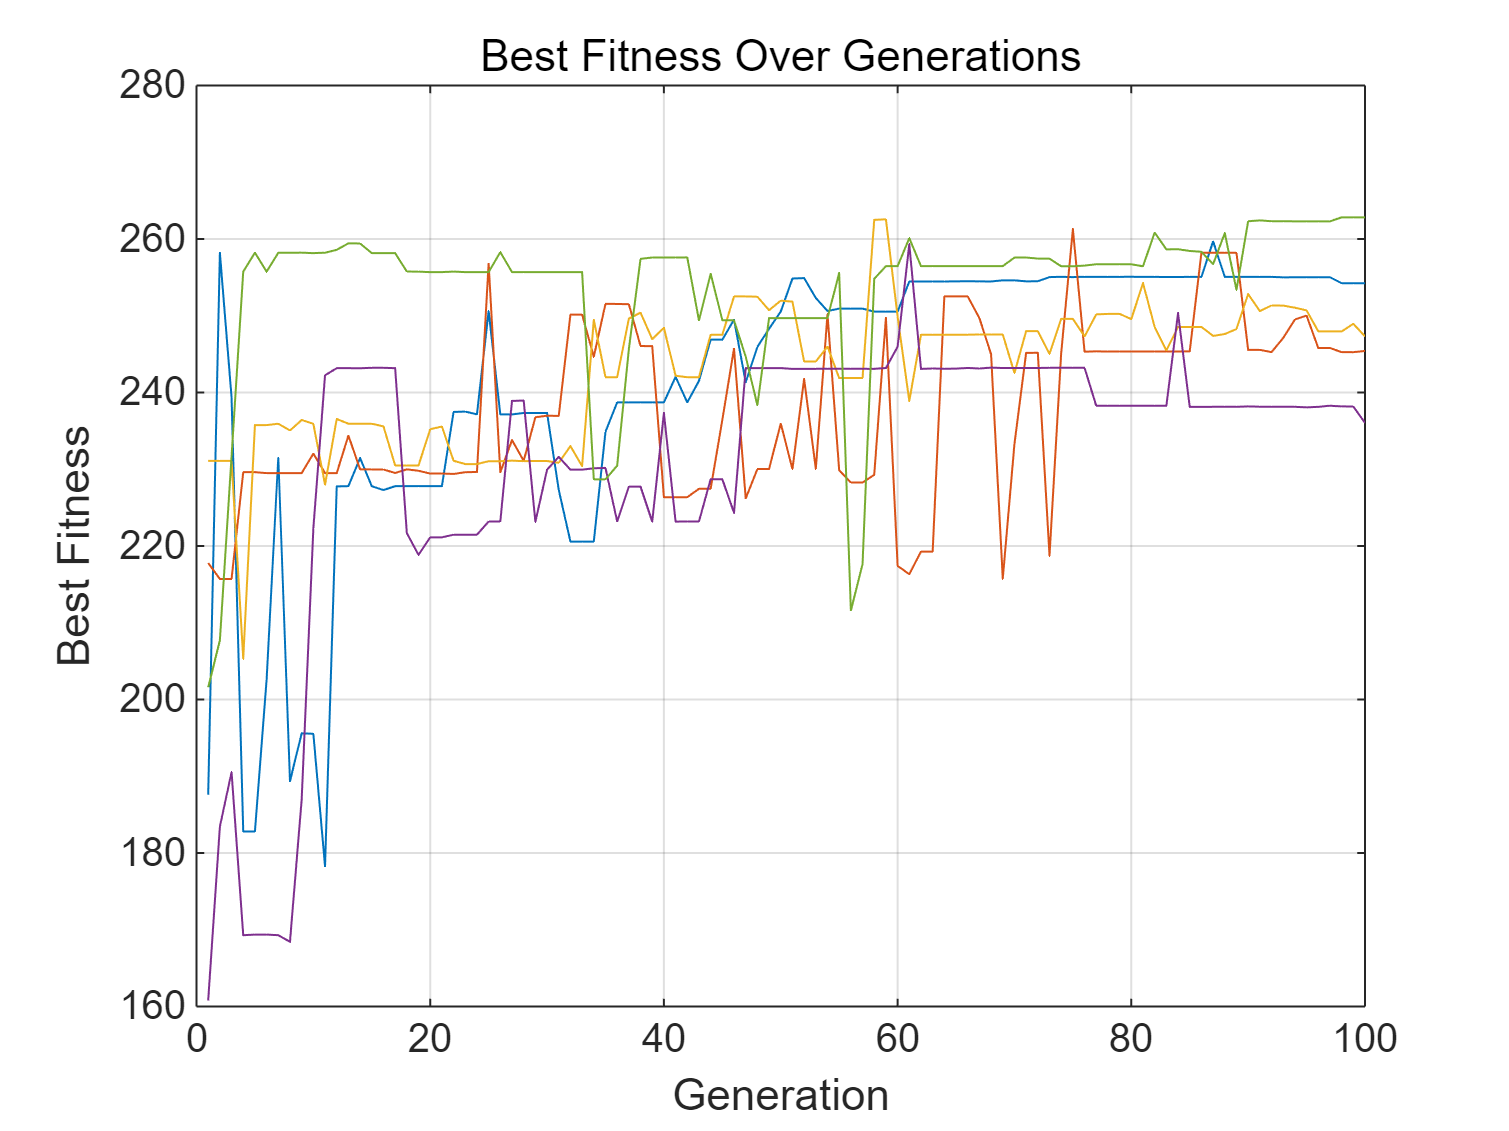     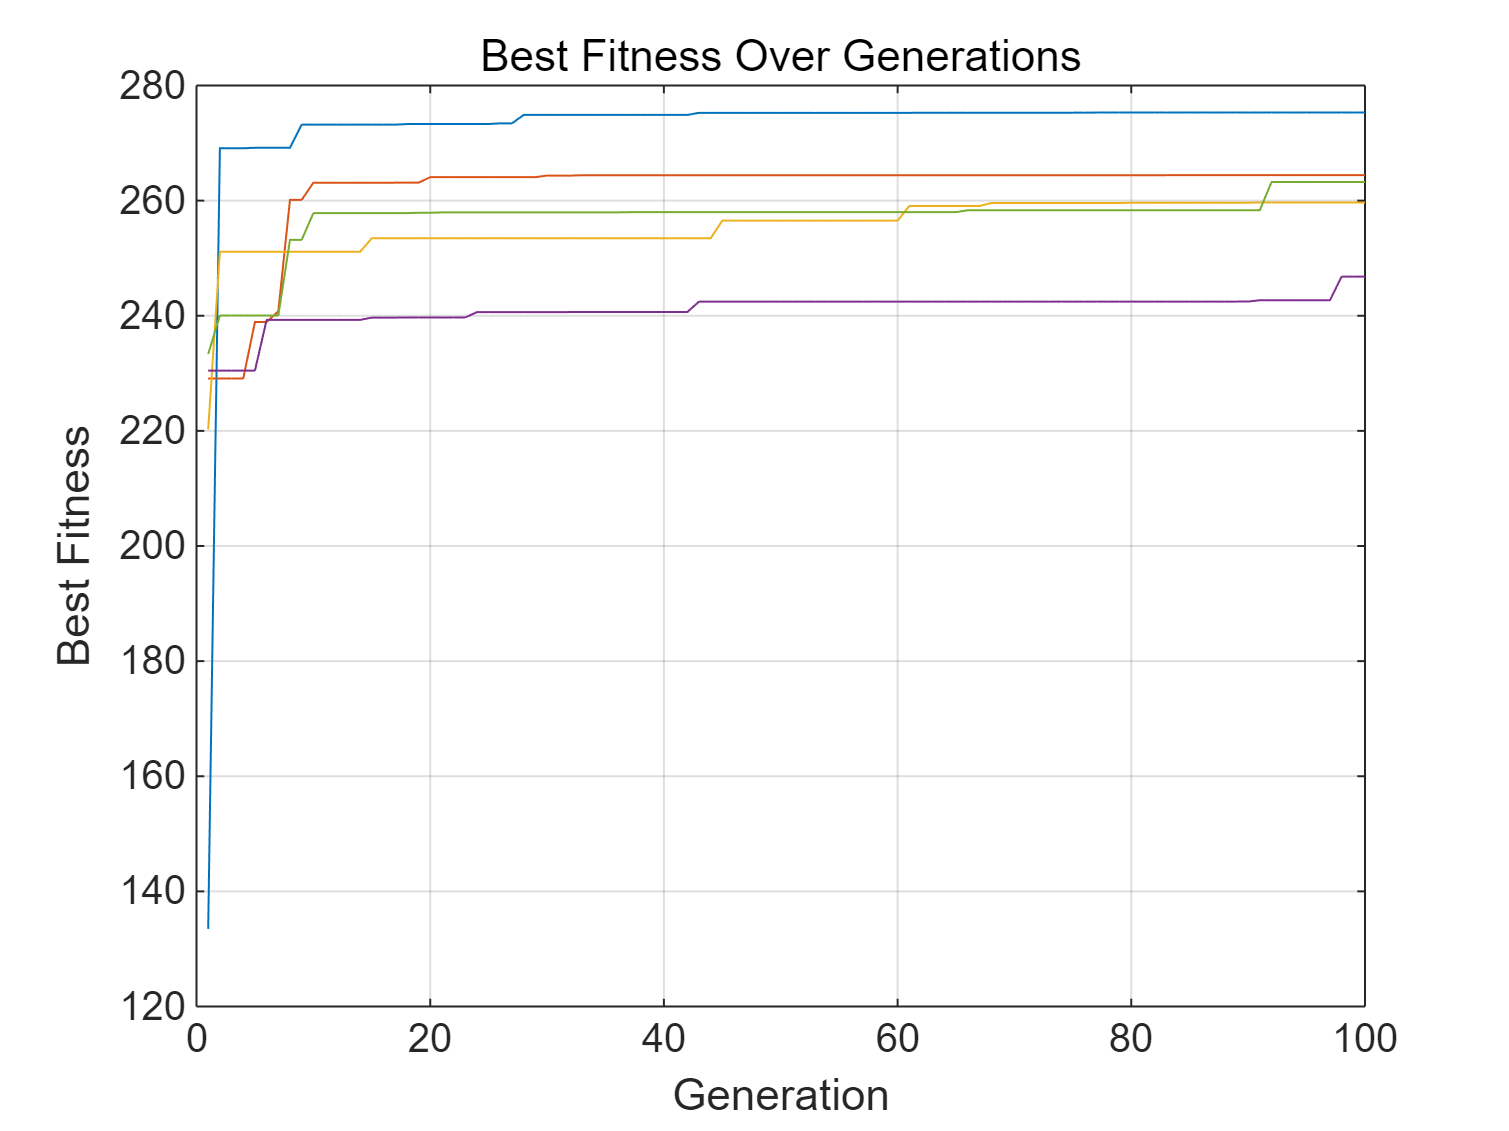

（figure1是单独使用了轮盘赌，figure2是两者结合）

 %%默认情况下是在选择完selectionStrategy后接最佳个体策略
 % 如若需要可直接使用单独策略(as follows:)

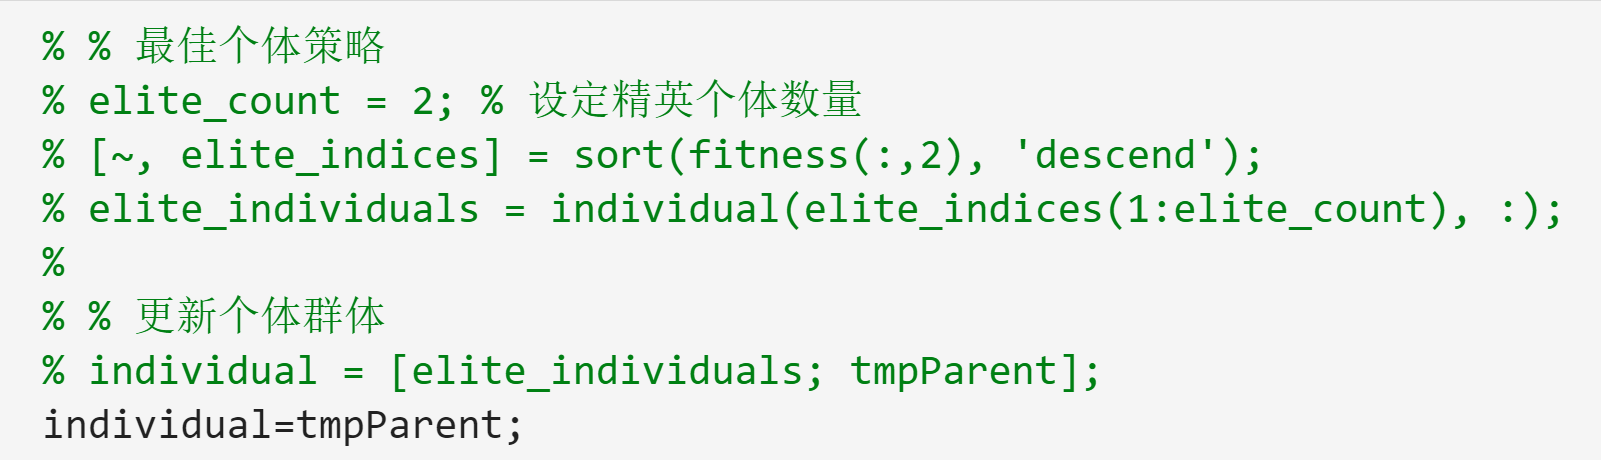

        % 最佳个体策略
        elite_count = 2; % 设定精英个体数量
        [~, elite_indices] = sort(fitness(:,2), 'descend');
        elite_individuals = individual(elite_indices(1:elite_count), :);

        % 更新个体群体
        individual = [elite_individuals; tmpParent];
        % individual=tmpParent;
        

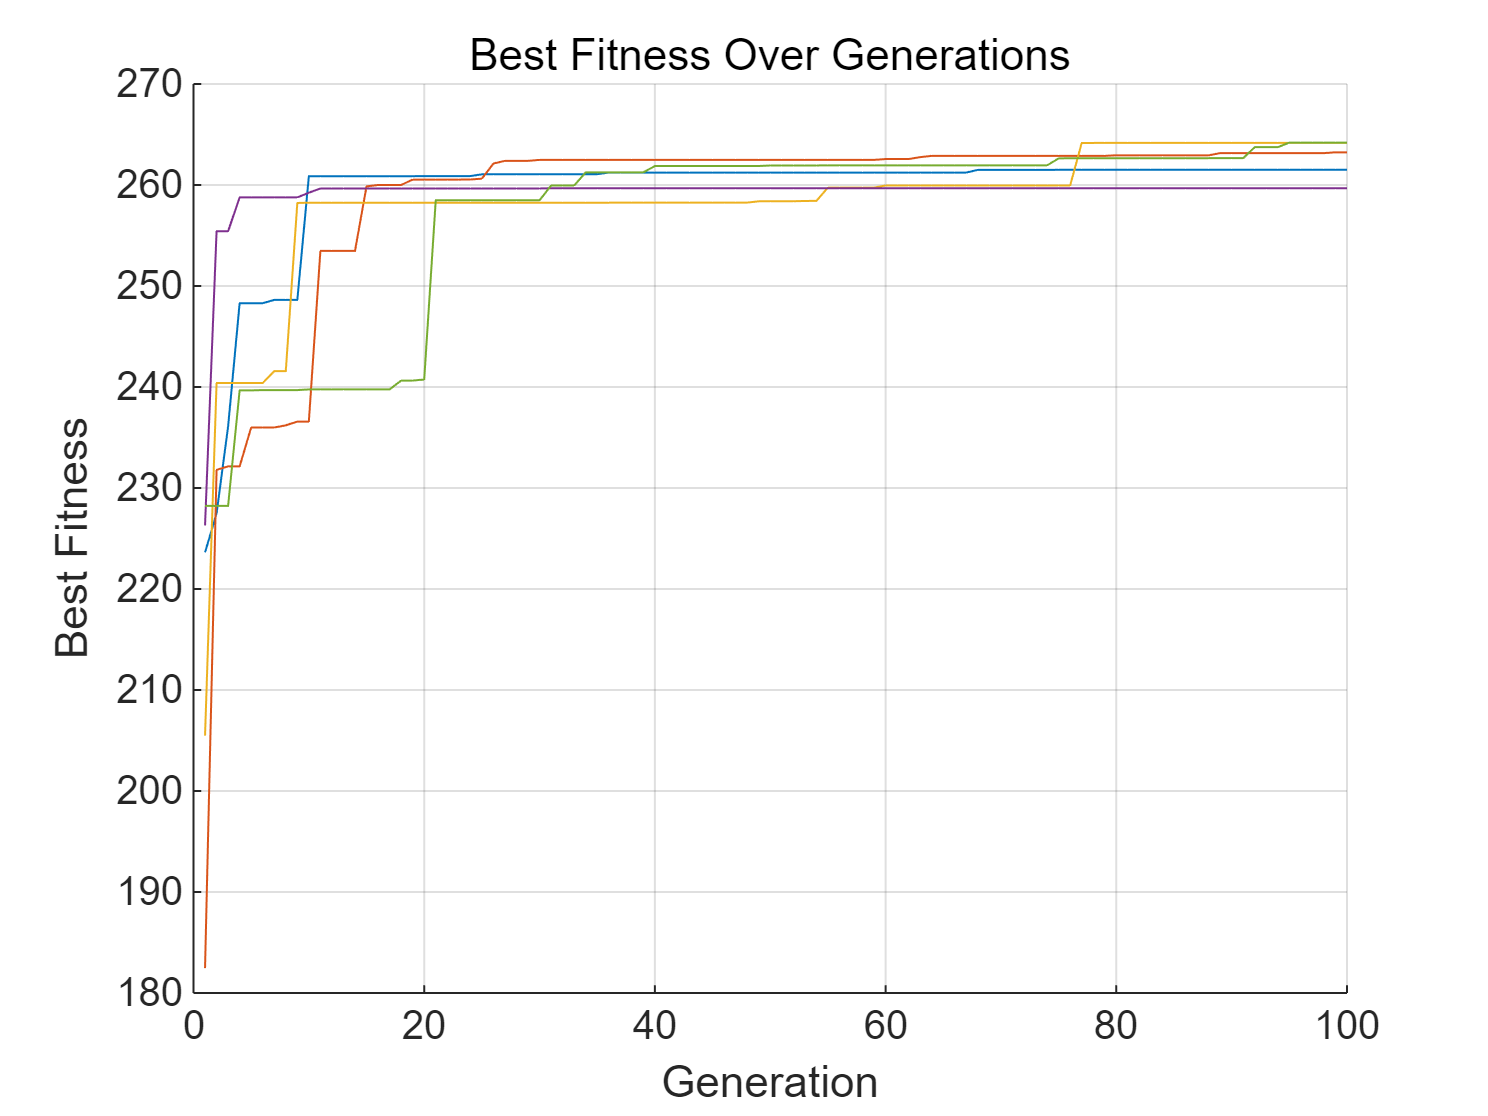


        % 找到当前代最优的个体
        [max_fitness, max_index] = max(fitness(:,2)); % 获取当前代的最大适应度及其索引
        if max_fitness > best_fitness
            best_fitness = max_fitness; % 更新最优适应度
            best_individual = individual(max_index, :); % 更新最优个体
        end

        % 记录当前代的最优个体和适应度
        best_fitness_history(cycle) = max_fitness; % 记录适应度
        best_individual_history(cycle, :) = individual(max_index, :); % 记录个体
    end

    % 保存每次运行的最优结果
    best_solution_all_runs(run, :) = best_individual; % 保存最优个体
    best_fitness_all_runs(run) = best_fitness; % 保存最优适应度

    % 可视化当前结果
    % figure(1);
    % hold on;
    % plot3(best_individual(2), best_individual(3), best_fitness, '*r'); % 绘制最优个体
    % hold off;

    % 可选：绘制每代最优适应度的变化
    figure(2);
    hold on;
    plot(1:num_generations, best_fitness_history);
    xlabel('Generation');
    ylabel('Best Fitness');
    title('Best Fitness Over Generations');
    grid on;
end


% 找到五次运行中最优的解
[global_best_fitness, best_run_index] = max(best_fitness_all_runs);
global_best_solution = best_solution_all_runs(best_run_index, :);

% 打印全局最优解
fprintf('Global best solution found: x = %.2f, y = %.2f, Fitness = %.2f\n', ...
    global_best_solution(2), global_best_solution(3), global_best_fitness);

Global best solution found: x = 6.29, y = 9.41, Fitness = 264.19
